clc; clear all; close all;

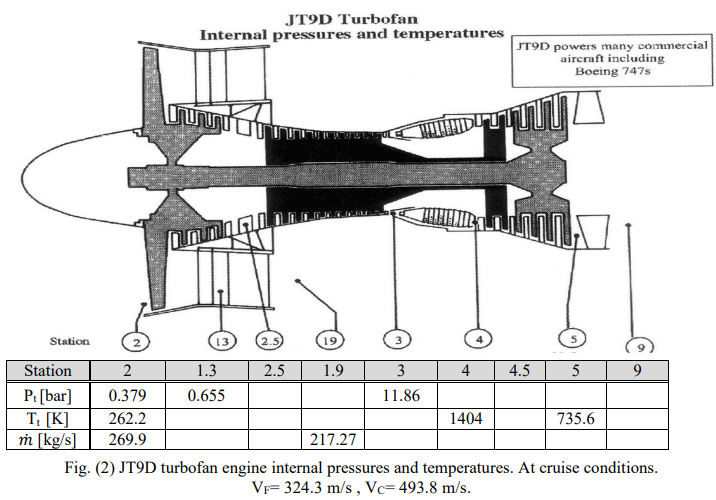

## Data


% Constant Values
Q_R = 2.8*10^7;
P_star_over_p_back=1.893;
gamma_F=1.4;gamma_C=1.4;gamma_T=1.3;gamma_nc=1.3;
e_F =0.86;e_C=0.88;e_T=0;%???   %From Tables 
% Given
Cp_3=1004.5;Cp_4=1088;
V_F=324.3; V_C=493.8;
Tt_2=262.2;    Pt_2=0.379;   m_dot_2=269.9;
               Pt_13=0.655;
                             m_dot_19=217.27;
               Pt_3=11.86;
Tt_4=1404;

Tt_5=735.6;   

R = 287; % Does it change with H ?? & also gamma ?!
Pb = Pt_2;
% syms Pb  % at flight condition

## ByPass Ratio { alpha }

m_dot_F=m_dot_19;
m_dot_C=m_dot_2-m_dot_19;
alpha=m_dot_F/m_dot_C

alpha = 4.1283

## Fuel to air Ratio { f } &  the fuel flow rate { m_dot_f }

Pi_F=Pt_13/Pt_2;
Taw_F=Pi_F^(1/e_F-1/gamma_F/e_F);
Tt_13=Tt_2*Taw_F;

Pi_C=Pt_3/Pt_13;
Taw_C=Pi_C^(1/e_C-1/gamma_C/e_C);
Tt_3=Tt_13*Taw_C;

f=(Cp_4*Tt_4 - Cp_3*Tt_3)/(Q_R - Cp_4*Tt_4)

f = 0.0271

m_dot_f=f*m_dot_C*60*60 % kg/h

m_dot_f = 5.1433e+03

## Fan, core and total static thrust and compare your answersto the specified thrust

% For Fan {13}
%     Pb= solve(V_F==((2*gamma_F/(gamma_F-1))*R*Tt_13*(1-(Pb/Pt_13)^(1-1/gamma_F)))^0.5 , Pb)
%     Pb= vpa(Pb,8)
    if Pt_13/Pb < P_star_over_p_back 
     M_F=(2/(gamma_F-1)*((Pt_13/Pb)^(1-1/gamma_F)-1))^0.5; %must be < 1
     F_F=m_dot_F*V_F
    else
     % ????????????
    end

F_F = 7.0461e+04


%For Core Fan {5:9}

% Assume Choked Core
M_C=1;
F_C=(1+f)*m_dot_C*V_C

F_C = 2.6694e+04


%Total Force
F=(F_F+F_C)/1000  %kN

F = 97.1548

## Effective jet velocity, specific thrust

V_C

V_C = 493.8000

ST=F*1000/(m_dot_C+m_dot_F)

ST = 359.9661

## Thermal efficiency

eta_th=(m_dot_F*V_F^2+m_dot_C*V_C^2)/(2*m_dot_f/60/60*Q_R)*100

eta_th = 44.6006

## Engine thrust specific fuel consumption

S =m_dot_f/F %mg/N.s

S = 52.9393

## Fan and core nozzles exit Mach number

M_F

M_F = 0.9198

M_C

M_C = 1